# Set Based Estimator Testing

## Setup

clear
close all

#### Simulation Settings

tf = 1;
dt = 0.01;
tspan = 0:dt:tf;

Input

omegaInput = 5;
inputFunction = @(t) sin(omegaInput * t);
U = inputFunction(tspan);

#### System Setup

sysType = "springMassDamper";

switch sysType
    case {"springMassDamper"}

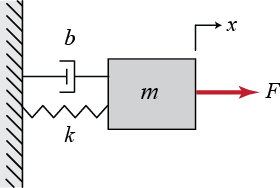

        m = 1;
        k = 1;
        b = 1;
        A = [0, 1; 
            -k/m, -b/m];
        B = [0;
            -1/m];
        C = [1, 0];
        D = [0];
        sys = ss(A,B,C,D);
end
 [numStates, numInputs] = size(B);
 numOutputs = size(C,1);
%  sys.u = 'u';
%  sys.y = 'y';

#### Estimator Setup

Nominal


$$\dot{\hat{x}} = (A + LC) \hat{x} + B u + Ly$$


lambda_obsv = [-1, -1.5];
L = place(A',C',lambda_obsv).';
sys_obsv = estim(sys,L,1,1);

## Simulation

% Setup
x_0 = 10 * rand(2,1);
x_hat_0 = x_0 + 0.1 * rand(2,1);

% Initialization
x = x_0;
x_hat = x_hat_0;

% Evolution
for k = 1:length(tspan)
    % Inputs and Measurements
    u = U(:,k);
    y = C * x + D * u;
    y_hat = C * x_hat;

    % State Equations
    dx = A * x + B * u;
    dx_hat = A * x_hat + B * u + L*(y - y_hat);
    
    % Euler Update
    x = x + dx * dt;
    x_hat = x_hat + dx_hat * dt;
    
    % Store Values
    X(:,k) = x;
    X_hat(:,k) = x_hat;
    Y(:,k) = y;
    Y_hat(:,k) = y_hat;
end









